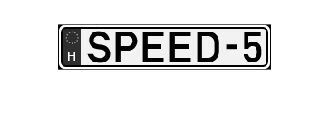

np = imread('np2.png');
np_gray = rgb2gray(np);
imshow(np_gray);

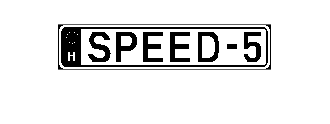

np_binarize = imbinarize(np_gray);
imshow(np_binarize);

np_clear = imclearborder(np_binarize, 8);
imshow(np_clear);

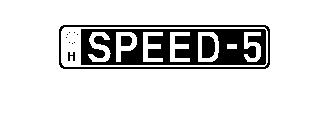

%np_switchcolour = logical(1 - np_clear);
np_switchcolour = logical(1 - np_binarize);
imshow(np_switchcolour);

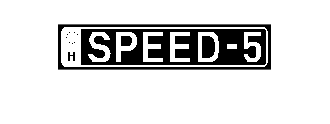

np_clear2 = imclearborder(np_switchcolour, 8);
imshow(np_clear2);

np_clean = bwareaopen(np_clear2, 10);
imshow(np_clean);

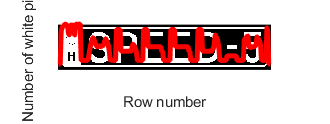

whitecount = sum(np_clean,1);
imshow(np_clean);
hold on
plot(max(whitecount)-whitecount,'r','LineWidth',3);
xlabel('Row number');
ylabel('Number of white pixels');
grid on
axis tight;

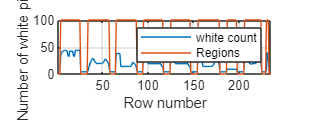

regions = whitecount > 5;
plot(whitecount);
hold on
plot(regions*100)
hold off
xlabel('Row number');
ylabel('Number of white pixels');
grid on
axis tight
legend('white count', 'Regions');

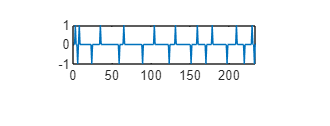

plot(diff(regions));

startIdx = [1 find(diff(regions)==1)];
endIdx = [find(diff(regions)==-1) length(regions)];
regions = endIdx - startIdx;
widthThreshold = mean(regions);

[labeledImage, numBlobs] = bwlabel(np_clean);
props = regionprops(labeledImage, 'BoundingBox');
for k = 1 : numBlobs
    thisBB = props(k).BoundingBox;
    thisImage{k} = imcrop(np_clean, thisBB);
    results{k} = ocr(thisImage{k},'TextLayout','Block');
    num_plate{k} = results{k}.Text;
    drawnow;

end

Unable to perform assignment because brace indexing is not supported for variables of this type.

% Convert characters to string 
num_plate2 = convertCharsToStrings(num_plate);
num_plate2 = regexprep(num_plate,'\n+','');
disp(num_plate2);

result = ocr(np_clean);
num_plate = result.Text;
disp(num_plate);

SPEED-5


